# Special Topics of Mechatronics - Inverted Pendulum

## Prepare Simscape Multibody Simulation

Import CAD files, created by *Simscape Multibody Link*,  via *Command Window*:

Run `invertedPendulum_DataFile.m`, generated by the `smimport`-function, to load CAD parameter.

The data in this file sets the block parameter values in the *Simscape Multibody* model.

inverted_pendulum_DataFile;

## 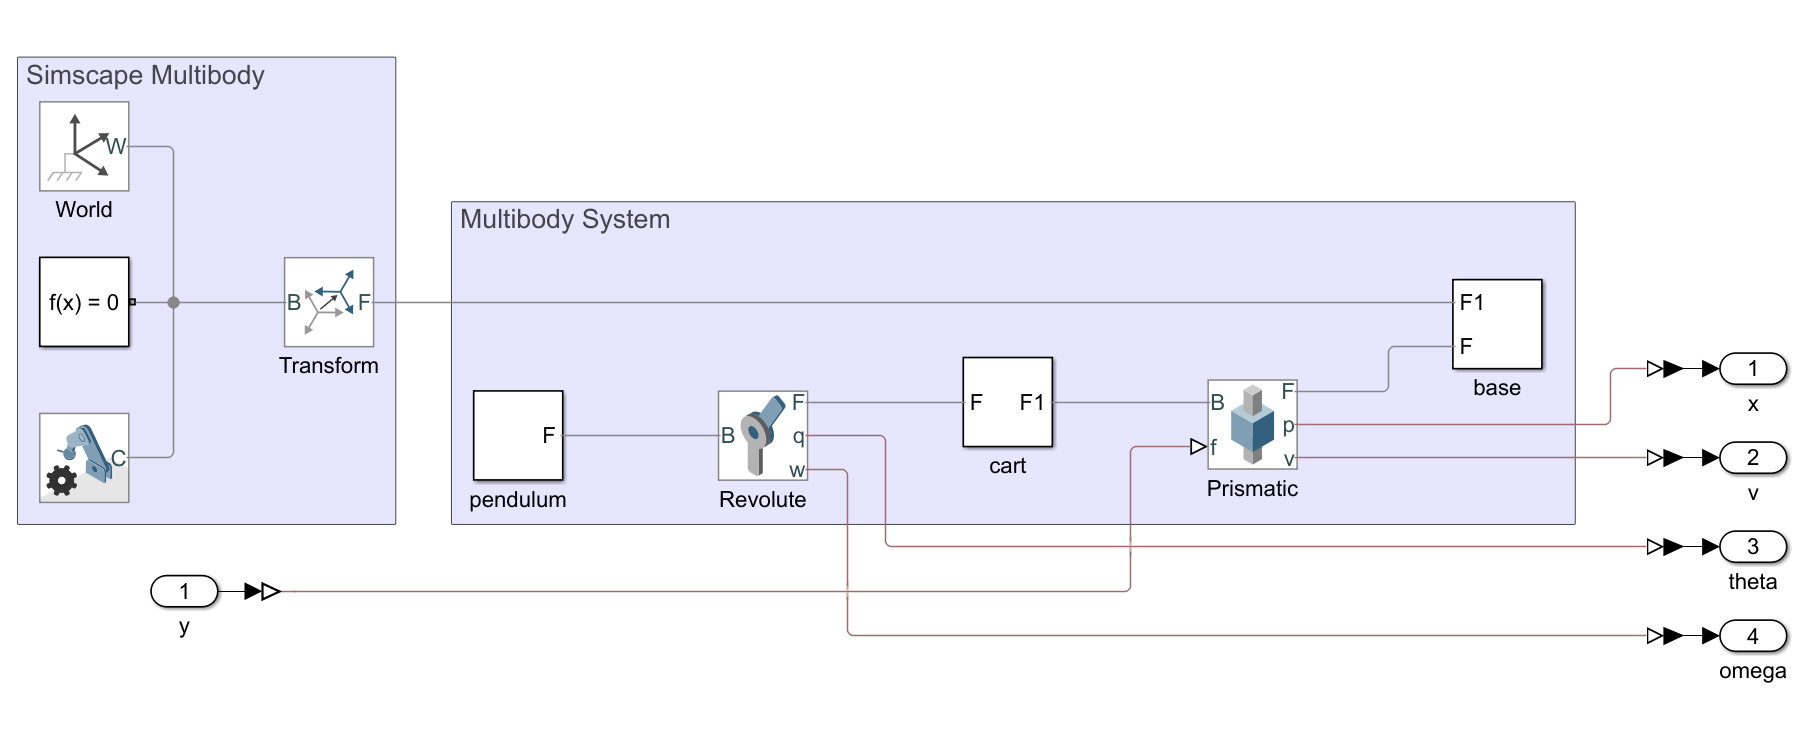

## Prepare Simscape Multibody Simulation

(overwrite some of the  `invertedPendulum_DataFile.m params`)

% starting positions
x_0 = 0;                                % [m] (0m --> middle of the track)
theta_0 = 4;                            % [deg] (0° --> upright)

% starting velocities
v_0 = 0;                                % [m/s]
omega_0 = 0;                            % [deg/s]

% damping
D = 0.00001;                            % [N/(m/s)] track-cart damping
d = 0.000001;                           % [N*m/(deg/s)] cart-pendulum damping

## Run Simulation

filename = 'free_system.slx';
%open(filename);
sim_data = sim(filename);

## Show timeseries plots

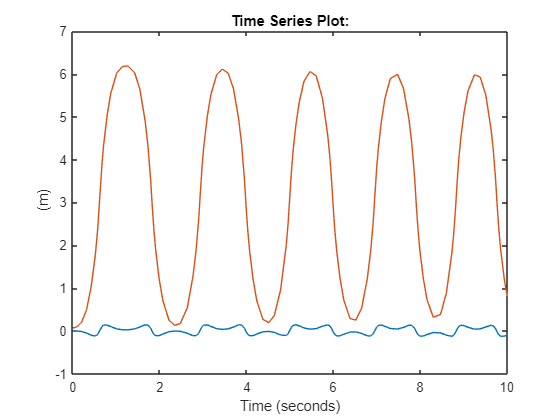

plot(sim_data.find('x'));
hold on;
plot(sim_data.find('theta'));
hold off;

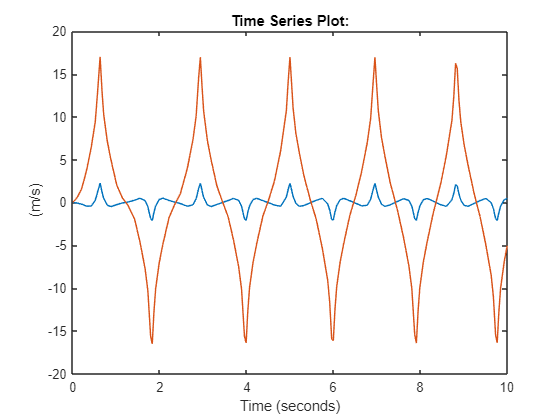

plot(sim_data.find('v'));
hold on;
plot(sim_data.find('omega'));